Mp = 0.15;
zeta = -log(Mp)/(sqrt(pi^2 + log(Mp)^2));

ts = 4;
Wn = 4/(ts*zeta);

beta = acos(zeta);
beta = rad2deg(beta);
xpoint = -zeta*Wn;
tan_beta = tan((beta*pi)/180);
ypoint = tan_beta*zeta*Wn;

num1 = 15.25;
den1 = [1 13.9 15.24 0];
g1 = tf (num1,den1);
pole(g1);

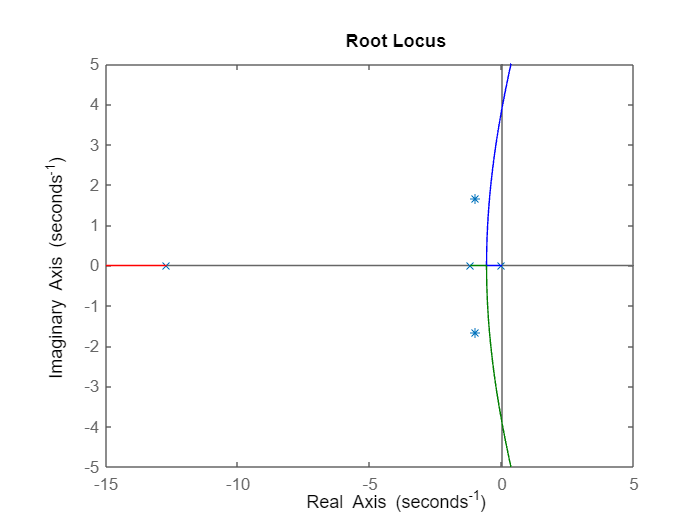

rlocusplot (g1);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

z = 1.25;
teta_p = 48;
x = ypoint/(tan((teta_p*pi)/180));
p = x + 1

p = 2.4911

s = -1 + 1.65j ;
num2 = 15.25*(s+z);
den2 = (s+p)*s*(s+1.2)*(s+12.7);
k = abs(den2/num2)

k = 3.3110

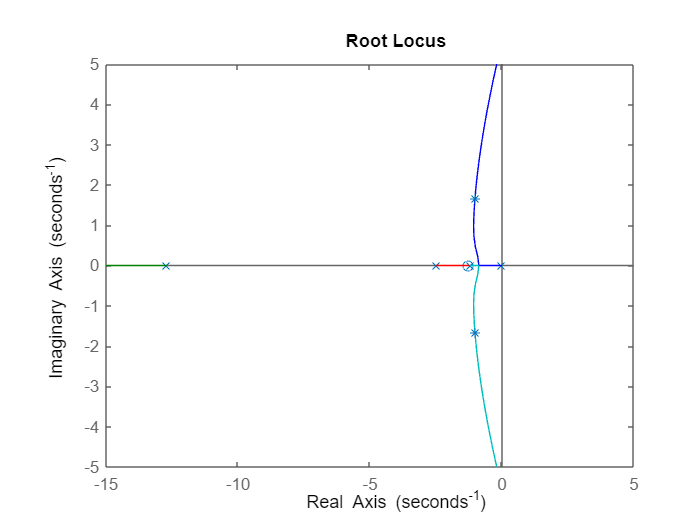

num3 = [k*15.25 k*15.25*z];
den3 = [1 13.9+p p*13.9+15.24 15.24*p 0];
g2 = tf(num3,den3);
rlocusplot (g2);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

%(g2)

K_old = 1.662;
K_new = 34;
z2 = 0.1/10

z2 = 0.0100

p2 = (z2*K_old)/K_new

p2 = 4.8882e-04

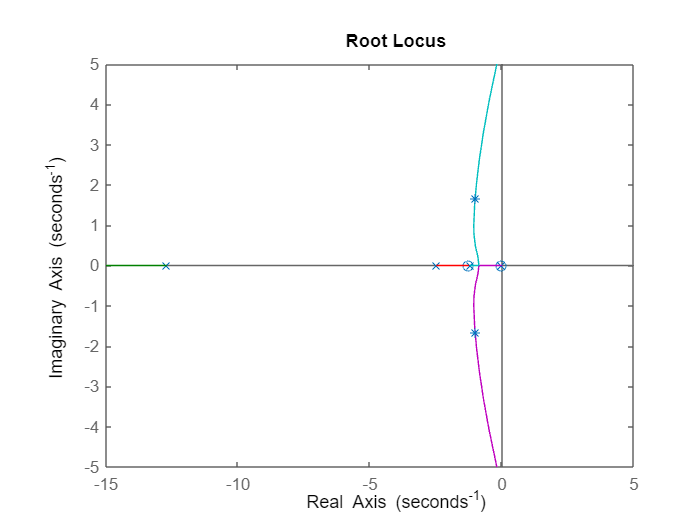

num4 = [50.4933 63.6215 0.6311];
den4 = [1 16.3916 49.8736 37.988 0.0186 0];
g3 = tf(num4,den4);
h = rlocusplot (g3);
xlim([-15, 5]);
ylim([-5, 5]);
hold on
points = [xpoint + ypoint*1i, xpoint - ypoint*1i];
plot(points, '*');
hold off

sisotool(g3)